#  ENME462 Studio 8 Root Locus Basics

by Xie Zheng

Section 0101 W 1:00PM - 2:50PM

Github: [https://github.com/XieGT/Control_Studios](https://github.com/XieGT/Control_Studios)

## Root Locus

- It is a plot of the path of the roots of the characteristic equation (closed-loop system poles) as one system parameter is varied.

- Number of branches is the same as the number of closed-loop poles.

- It is symmetric about the real axis. 

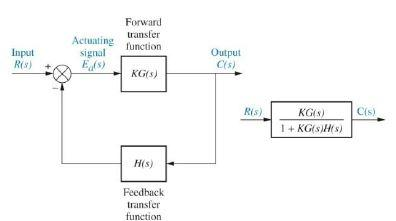

**Characteristic equation** 


$$1+KG(s)H(s)=0 $$


If We let $G(s)H(s)=P(s)=\frac{Z_m(s)}{P_n(s)}=\frac{\Pi_{i=1}^{m}(s+z_i)}{\Pi_{j=1}^{n}(s+p_j)}$

then the char. eqn is $1+K\frac{\Pi_{i=1}^{m}(s+z_i)}{\Pi_{j=1}^{n}(s+p_j)}=0$

which is equivalent to 


$$\prod_{j=1}^{n}(s+p_j)+K\prod_{i=1}^{m}(s+z_i)=0\quad \stackrel{K=0}{\longrightarrow} \qquad \prod_{j=1}^{n}(s+p_k)=0$$


Conclusion: The root locus **start** at OL system **poles** with $K=0$


$$\prod_{j=1}^{n}(s+p_j)+K\prod_{i=1}^{m}(s+z_i)=0\quad \stackrel{K=\infty}{\longrightarrow} \qquad \prod_{i=1}^{m}(s+z_i)=0$$


Conclusion: The root locus **end** at OL system **zeros** with $K\rightarrow \infty$

## Example 1

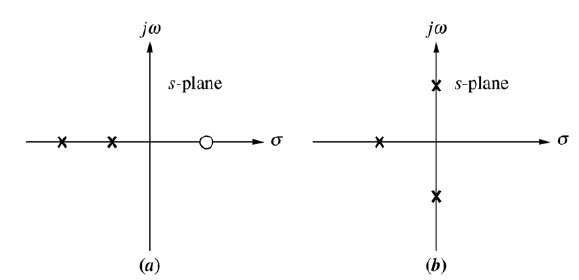

**a)**$G(s)H(s)=\frac{s-1}{(s+1)(s+2)}$                          **b)** $G(s)H(s)=\frac{1}{(s+1)(s^2+1)}$

Char eqn :

a)     $(s+1)(s+2) + K(s-1)=0 \qquad \rightarrow  s^2 +(K+3)s +(2-K)=0$

b)     $(s+1)(s^2+1)+K =0 \qquad \rightarrow s^3 +s^2+ s + (K+1) =0$

clc; clear all;
K = 0:10:100;
N = length(K);
CP_a = zeros(2,N);
CP_b = zeros(3,N);

for n = 1:N
    Coeff_a = [1, (3 + K(n)), (2 - K(n))];
    CP_a(:,n) = roots(Coeff_a);
    Coeff_b = [1, 1, 1, (K(n) + 1)];
    CP_b(:,n) = roots(Coeff_b);
end

CP_a = CP_a'

CP_a =    -2.0000   -1.0000
  -13.5887    0.5887
  -23.7577    0.7577
  -33.8277    0.8277
  -43.8663    0.8663
  -53.8907    0.8907
  -63.9076    0.9076
  -73.9199    0.9199
  -83.9294    0.9294
  -93.9368    0.9368


CP_b = CP_b'

CP_b =   -1.0000 + 0.0000i  -0.0000 - 1.0000i  -0.0000 + 1.0000i
  -2.4391 + 0.0000i   0.7195 - 1.9981i   0.7195 + 1.9981i
  -3.0000 + 0.0000i   1.0000 - 2.4495i   1.0000 + 2.4495i
  -3.3950 + 0.0000i   1.1975 - 2.7744i   1.1975 + 2.7744i
  -3.7097 + 0.0000i   1.3548 - 3.0359i   1.3548 + 3.0359i
  -3.9754 + 0.0000i   1.4877 - 3.2581i   1.4877 + 3.2581i
  -4.2077 + 0.0000i   1.6039 - 3.4532i   1.6039 + 3.4532i
  -4.4154 + 0.0000i   1.7077 - 3.6282i   1.7077 + 3.6282i
  -4.6040 + 0.0000i   1.8020 - 3.7876i   1.8020 + 3.7876i
  -4.7775 + 0.0000i   1.8888 - 3.9345i   1.8888 + 3.9345i
  -4.9386 + 0.0000i   1.9693 - 4.0710i   1.9693 + 4.0710i


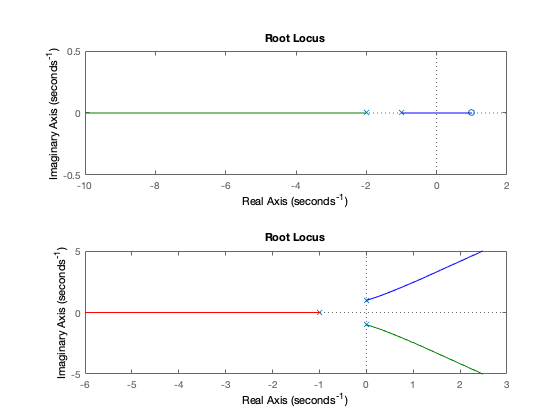


s = zpk('s');
GH_a = (s-1) / ((s+1)*(s+2));
GH_b =  1 / ((s+1)*(s^2+1));

figure(1)
subplot(2,1,1)
rlocus(GH_a);
subplot(2,1,2)
rlocus(GH_b);

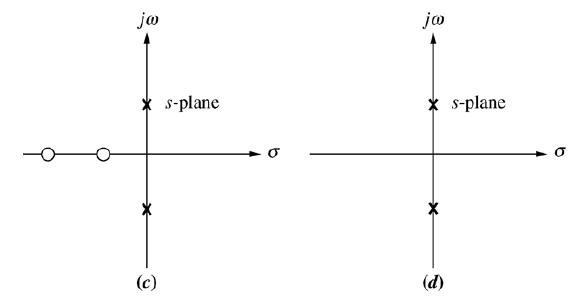

**c)** $G(s)H(s)=\frac{(s+1)(s+2)}{(s^2+1)}$**                                d)** $G(s)H(s)=\frac{1}{s^2+1}$

Char eqn :

c)     $s^2 +1 + K(s+1)(s+2)=0 \qquad \rightarrow  
(K+1)s^2 +3Ks+(2K+1)=0$

d)     $(s^2+1)+K =0 \qquad \rightarrow 
s^2 + (K+1) =0$

K = 0:10:100;
N = length(K);
CP_c = zeros(2,N);
CP_d = zeros(2,N);

for n = 1:N
    Coeff_c = [(K(n)+1), 3*K(n), (2*K(n) +1)];
    CP_c(:,n) = roots(Coeff_c);
    Coeff_d = [1, 0, (K(n)+1)];
    CP_d(:,n) = roots(Coeff_d);
end

CP_c = CP_c'

CP_c =    0.0000 - 1.0000i   0.0000 + 1.0000i
  -1.3636 - 0.2227i  -1.3636 + 0.2227i
  -1.7260 + 0.0000i  -1.1312 + 0.0000i
  -1.8250 + 0.0000i  -1.0782 + 0.0000i
  -1.8708 + 0.0000i  -1.0560 + 0.0000i
  -1.8975 + 0.0000i  -1.0437 + 0.0000i
  -1.9150 + 0.0000i  -1.0358 + 0.0000i
  -1.9274 + 0.0000i  -1.0304 + 0.0000i
  -1.9366 + 0.0000i  -1.0264 + 0.0000i
  -1.9437 + 0.0000i  -1.0233 + 0.0000i
  -1.9494 + 0.0000i  -1.0209 + 0.0000i


CP_d = CP_d'

CP_d =    0.0000 - 1.0000i   0.0000 + 1.0000i
   0.0000 - 3.3166i   0.0000 + 3.3166i
   0.0000 - 4.5826i   0.0000 + 4.5826i
   0.0000 - 5.5678i   0.0000 + 5.5678i
   0.0000 - 6.4031i   0.0000 + 6.4031i
   0.0000 - 7.1414i   0.0000 + 7.1414i
   0.0000 - 7.8102i   0.0000 + 7.8102i
   0.0000 - 8.4261i   0.0000 + 8.4261i
   0.0000 - 9.0000i   0.0000 + 9.0000i
   0.0000 - 9.5394i   0.0000 + 9.5394i
   0.0000 -10.0499i   0.0000 +10.0499i


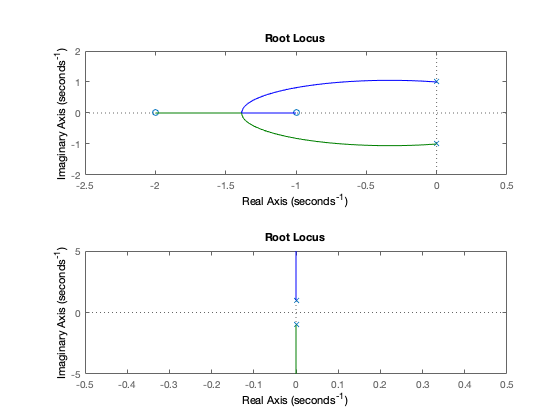


GH_c = (s+1)*(s+2)/(s^2+1);
GH_d = 1/(s^2 +1);
figure(2)
subplot(2,1,1)
rlocus(GH_c)
subplot(2,1,2)
rlocus(GH_d)

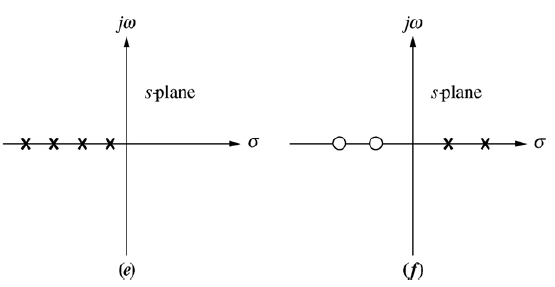

**e)** $G(s)H(s)=\frac{1}{(s+1)(s+2)(s+3)(s+4)}$   **f)** $G(s)H(s)=\frac{(s+1)(s+2)}{(s-1)(s-2)}$

Char eqn :

e)     $(s+1)(s+2)(s+3)(s+4)+K=0 \qquad \rightarrow  s^4 + 10s^3+35s^2 +50*s +(24+K)=0$

f)     $(s-1)(s-2)+K(s+1)(s+2) =0 \qquad \rightarrow 
(K+1)s^2+(3K-3)s+(2K+2)=0$

K = 0:1:10;
N = length(K);
CP_e = zeros(4,N);
CP_f = zeros(2,N);

for n = 1:N
    Coeff_e = [1, 10, 35, 50, (24+K(n))];
    CP_e(:,n) = roots(Coeff_e);
    Coeff_f = [(K(n)+1), (3*K(n)-3), (2*K(n)+2)];
    CP_f(:,n) = roots(Coeff_f);
end

CP_e = CP_e'

CP_e =   -4.0000 + 0.0000i  -3.0000 + 0.0000i  -2.0000 + 0.0000i  -1.0000 + 0.0000i
  -3.6180 - 0.0000i  -3.6180 + 0.0000i  -1.3820 - 0.0000i  -1.3820 + 0.0000i
  -3.6939 - 0.4188i  -3.6939 + 0.4188i  -1.3061 - 0.4188i  -1.3061 + 0.4188i
  -3.7525 - 0.5646i  -3.7525 + 0.5646i  -1.2475 - 0.5646i  -1.2475 + 0.5646i
  -3.8012 - 0.6656i  -3.8012 + 0.6656i  -1.1988 - 0.6656i  -1.1988 + 0.6656i
  -3.8432 - 0.7445i  -3.8432 + 0.7445i  -1.1568 - 0.7445i  -1.1568 + 0.7445i
  -3.8805 - 0.8099i  -3.8805 + 0.8099i  -1.1195 - 0.8099i  -1.1195 + 0.8099i
  -3.9142 - 0.8660i  -3.9142 + 0.8660i  -1.0858 - 0.8660i  -1.0858 + 0.8660i
  -3.9450 - 0.9155i  -3.9450 + 0.9155i  -1.0550 - 0.9155i  -1.0550 + 0.9155i
  -3.9735 - 0.9598i  -3.9735 + 0.9598i  -1.0265 - 0.9598i  -1.0265 + 0.9598i
  -4.0000 - 1.0000i  -4.0000 + 1.0000i  -1.0000 - 1.0000i  -1.0000 + 1.0000i


CP_f = CP_f'

CP_f =    2.0000 + 0.0000i   1.0000 + 0.0000i
   0.0000 - 1.4142i   0.0000 + 1.4142i
  -0.5000 - 1.3229i  -0.5000 + 1.3229i
  -0.7500 - 1.1990i  -0.7500 + 1.1990i
  -0.9000 - 1.0909i  -0.9000 + 1.0909i
  -1.0000 - 1.0000i  -1.0000 + 1.0000i
  -1.0714 - 0.9231i  -1.0714 + 0.9231i
  -1.1250 - 0.8570i  -1.1250 + 0.8570i
  -1.1667 - 0.7993i  -1.1667 + 0.7993i
  -1.2000 - 0.7483i  -1.2000 + 0.7483i
  -1.2273 - 0.7027i  -1.2273 + 0.7027i


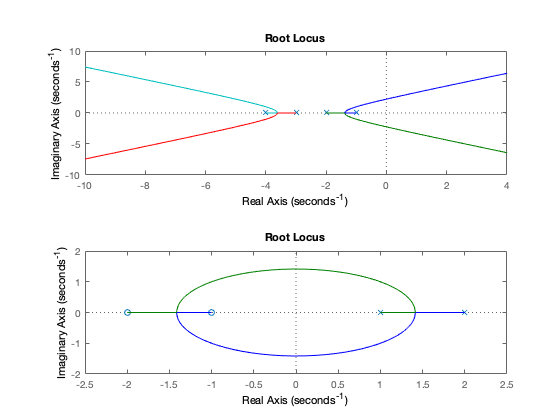


GH_e = 1/((s+1) * (s+2) *(s+3) *(s+4));
GH_f = (s+1)*(s+2) / ((s-1) * (s-2));
figure(3)
subplot(2,1,1)
rlocus(GH_e)
subplot(2,1,2)
rlocus(GH_f)

Steps for sketching a root locus

- Write the characteristic equation, locate the open loop poles & zeros.

- Locate the segments of the real axis ( it lies in a section of the real axis to the **left** of an** odd** number of real poles and zeros)

- Find the asymptotes( center: $\sigma_a=\left(\sum_{k=1}^{n}{-p_k}-\sum_{k=1}^{m}{-z_i}\right)/(n-m)$, with angle $\phi_{a}=\frac{2h+1}{n-m}\times180^o, \quad h=0,1,2...,n-m-1$) 

- Determine where the root locus crosses the imaginary axis (using the Routh-Hurwitz criterion).

- Determine the break-away / break-in point(s) on the real axis($\frac{dK}{ds}=0, \quad \frac{d^2K}{ds^2}=?$)

## Example 2

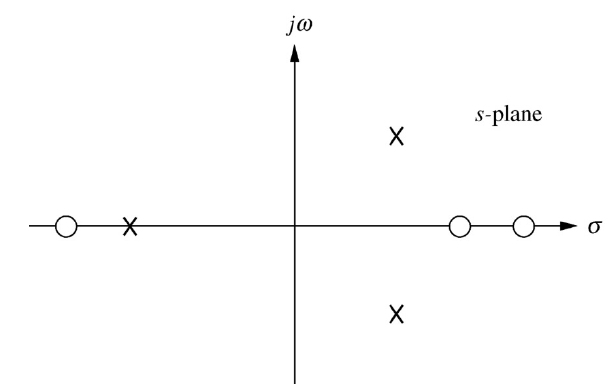


$$G(s)H(s)=\frac{(s-1)(s-2)(s+2)}{(s-1+i)(s-1-i)(s+1)}$$


% 1. locate the open loop poles (x) and zeros (o)
GH_poles = [ 1-1j, 1+1j, -1];
GH_zeros = [1, 2, -2];
% 2. odd poles on the real axis go left: o(-2) <--- x(-1)
% 3. find asymptotes
n = 3; % number of poles 
m = 3; % number of zeros

ans = 0

% 4. never cross imaginary axis
% 5. break away/ in point

syms s K
GH = (s-1)*(s-2)*(s+2) / ((s-1+1j)*(s-1-1j)*(s+1));
K = -1/GH;  % 1 + KGH = 0 => K = -1/(GH)
K = simplify(K)

$$K = \frac{s^{3}-s^{2}+2}{-s^{3}+s^{2}+4\,s-4}$$

dK = diff(K);
dK = simplify(dK)

$$dK = \frac{2\,\left(4\,s^{3}-5\,s^{2}+2\,s-4\right)}{{\left(-s^{3}+s^{2}+4\,s-4\right)}^{2}}$$

s = roots([4, -5, 2, -4])

s =    1.4021 + 0.0000i
  -0.0760 + 0.8411i
  -0.0760 - 0.8411i



GH_2 = zpk(GH_zeros,GH_poles,1)


GH_2 =
 
   (s-1) (s-2) (s+2)
  --------------------
  (s+1) (s^2 - 2s + 2)
 
Continuous-time zero/pole/gain model.



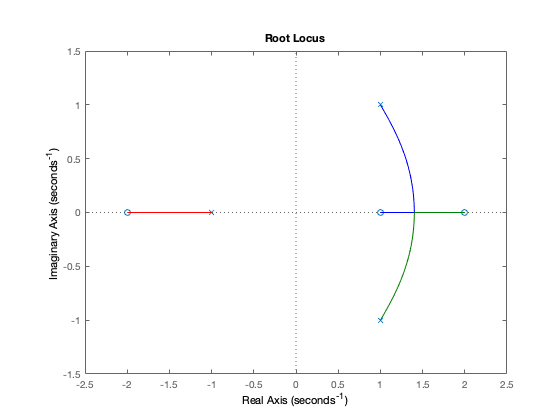

figure(4)
rlocus(GH_2)

## Example 3

For a unity-feedback system with a forward transfer function $G(s)=\frac{K}{s(s+6)(s+9)}$, plot the root locus and find breakaway points, asymptotes, and $j\omega$-axis crossing points.

char eqn:


$$1+G(s)=0 \qquad \rightarrow s(s+6)(s+9)+K=0\qquad \rightarrow s^3+15s^2+54s+K=0$$


% 1. locate the open loop poles (x) and zeros (o)
GH_poles = [0, -6, -9]

GH_poles =      0    -6    -9


GH_zeros = []


GH_zeros =

     []



% 2. odd poles on the real axis go left: o(-inf) <--- x(-9)
% 3. find asymptotes
n = 3; % number of poles
m = 0; % number of zeros
sigma_a = (sum(GH_poles) - sum(GH_zeros)) / (n-m)

sigma_a = -5

h = 0:1:n-m-1

h =      0     1     2


phi_a = (2.*h +1)./(n-m).*180

phi_a =     60   180   300


% 4. where the root locus crosses the imaginary axis
% RH table
% s3 = [1, 54]
% s2 = [15, K]
% s1 = [(15*54-K)/15, 0]
% s0 = [K]
K = 15*54 % s1 = [0,0]

K = 810

s = roots([1, 15, 54, 15*54])

s =  -15.0000 + 0.0000i
   0.0000 + 7.3485i
   0.0000 - 7.3485i


% 5. break away/in points
syms K s
K = -s^3 - 15*s^2 -54*s

$$K = -s^{3}-15\,s^{2}-54\,s$$

dK = diff(K)

$$dK = -3\,s^{2}-30\,s-54$$

s = roots([-3, -30, -54])

s =    -7.6458
   -2.3542


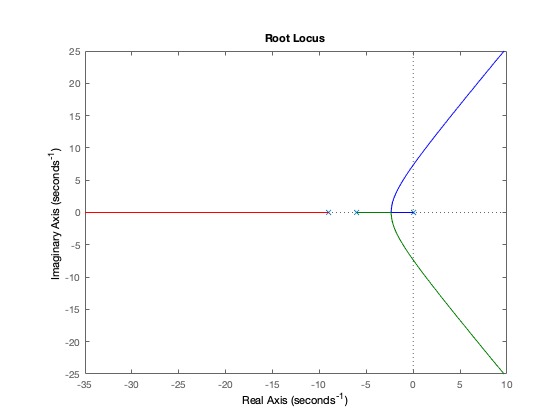


GH_3 = zpk(GH_zeros,GH_poles,1);
rlocus(GH_3)